# Figure 4A right

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A058_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 20×5 cell array
    {'RO DOX'     }    {[2 3 4]}    {[ 2]}    {[1]}    {[0]}
    {'2i DOX'     }    {[2 3 4]}    {[ 3]}    {[1]}    {[0]}
    {'RO+2i DOX'  }    {[2 3 4]}    {[ 4]}    {[1]}    {[0]}
    {'4/6i DOX'   }    {[2 3 4]}    {[ 5]}    {[1]}    {[0]}
    {'DMSO DOX'   }    {[2 3 4]}    {[ 6]}    {[1]}    {[0]}
    {'RO DMSO'    }    {[2 3 4]}    {[ 7]}    {[1]}    {[0]}
    {'2i DMSO'    }    {[2 3 4]}    {[ 8]}    {[1]}    {[0]}
    {'RO+2i DMSO' }    {[2 3 4]}    {[ 9]}    {[1]}    {[0]}
    {'4/6i DMSO'  }    {[2 3 4]}    {[10]}    {[1]}    {[0]}
    {'DMSO DMSO'  }    {[2 3 4]}    {[11]}    {[1]}    {[0]}
    {'500nM TAK'  }    {[5 6 7]}    {[ 2]}    {[1]}    {[0]}
    {'250nM TAK'  }    {[5 6 7]}    {[ 3]}    {[1]}    {[0]}
    {'125nM TAK'  }    {[5 6 7]}    {[ 4]}    {[1]}    {[0]}
    {'62.5nM TAK' }    {[5 6 7]}    {[ 5]}    {[1]}    {[0]}
    {'31.25nM TAK'}    {[5 6 7]}    {[ 6]}    {[1]}    {[0]}
    {'15.6nM TAK' }    {[5 6 7]}    {[ 7]}    {[1]}    {


framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
% 
for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
   S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

 drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,1)),1);
    apcGateAll = false(length(dat.POI(:,1)),1);
    cdkHighGate = false(length(dat.POI(:,1)),1);
crlGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
        if dat.POI(n,1) + round(20*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)) < .02;
            apcGateAll(n) = ~isnan(dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)));
        end
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) > .7;
        end
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) <numFrames - 1 * framesPerHr
            crlGate(n) = dat.crlNormAct(n,dat.POI(n,1) - 1 * framesPerHr) >  .5 & ...
               dat.crlNormAct(n,dat.POI(n,1) + 1 * framesPerHr) > .5;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
    S(i).apcGate = apcGate;
    S(i).apcGateAll = apcGateAll;

   S(i).crlGate = crlGate;
        S(i).cdkHighGate = cdkHighGate;

end

G1

conds=[20 11];
colors = [.5 .5 .5; .6 .9 .2];
POI_align = 3;
ally = [];
groups = [];
timeGate = [0 10];

for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,POI_align)) &  ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) & data.apcExpressGate & data.goodCdk;
sum(inds)
    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,1));
    yvals = yvals(yvals < 2000 & yvals >= 0);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 

end

ans = 918

ans = 366

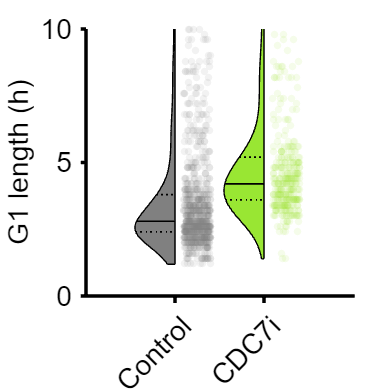


figure('Units', 'Inches', 'Position', [0, 0, 4 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'G1 length (h)'])


xticklabels({'Control','CDC7i'})
ylim([0 10])
 xtickangle(45)
axis square
set(gca,'fontsize',17,'linewidth',2)


 

p=mediantest(ally(groups==1),ally(groups==2))

p = 9.2579e-52


 % print_pdf(['fig_4A_right.pdf'])